# Q1 Polynomial Approximations

% Input trigonometric function
f = @(t) 2*sin((1/4)*pi*t)+3*cos((1/2)*pi*t);

% Input orders
n_1 = 5;
n_2 = 10;
n_3 = 25;
n_4 = 50;
n_5 = 100;

% Input time vector
t = linspace(0, 1, 1000);

% turn off warning message
warning('off');

% Generate Bernstein approximations
[Bnft_1, polyApprox_1] = Q1BernsteinApprox(f, n_1, t);
[Bnft_2, polyApprox_2] = Q1BernsteinApprox(f, n_2, t);
[Bnft_3, polyApprox_3] = Q1BernsteinApprox(f, n_3, t);
[Bnft_4, polyApprox_4] = Q1BernsteinApprox(f, n_4, t);
[Bnft_5, polyApprox_5] = Q1BernsteinApprox(f, n_5, t);

% turn warning back on
warning('on');

% Calculate function values
% fVals = f(t);

% Calculate maximum error between f and its Bernstein approximation
err_1 = max(abs(f(t) - Bnft_1));
err_2 = max(abs(f(t) - Bnft_2));
err_3 = max(abs(f(t) - Bnft_3));
err_4 = max(abs(f(t) - Bnft_4));
err_5 = max(abs(f(t) - Bnft_5));


% Display maximum error between f and its Bernstein approximation
fprintf('Max absolute difference for order %d: %f\n', n_1, err_1);

Max absolute difference for order 5: 0.147352


fprintf('Max absolute difference for order %d: %f\n', n_2, err_2);

Max absolute difference for order 10: 0.074984


fprintf('Max absolute difference for order %d: %f\n', n_3, err_3);

Max absolute difference for order 25: 0.030340


fprintf('Max absolute difference for order %d: %f\n', n_4, err_4);

Max absolute difference for order 50: 0.015231


fprintf('Max absolute difference for order %d: %f\n', n_5, err_5);

Max absolute difference for order 100: 0.007631


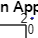


% Plot function f and each of its approximations
figure;
plot(t, f(t), 'k', t, Bnft_1, 'r', t, Bnft_2, 'g', t, Bnft_3, 'm', t, Bnft_4, 'y', t, Bnft_5, 'b', 'linewidth', 2);

% Format plot
title('Bernstein Approximations');
xlabel('t');
ylabel('f(t)');
legend('f(t)', sprintf('B_{%d}f(t)', n_1), sprintf('B_{%d}f(t)', n_2), sprintf('B_{%d}f(t)', n_3), sprintf('B_{%d}f(t)', n_4), sprintf('B_{%d}f(t)', n_5));
grid on;


% Display Bernstein polynomial representation
fprintf('The bernstein polynomial representation for the orders of:\n');

The bernstein polynomial representation for the orders of:


fprintf('n = %d, is: %s \n', n_1, polyApprox_1);

n = 5, is: 3(1 - t)^(5) + 15.8302t^1(1 - t)^(4) + 30.4508t^2(1 - t)^(3) + 26.7134t^3(1 - t)^(2) + 10.5131t^4(1 - t)^(1) + 1.4142t^5(1 - t)^(0) 


fprintf('n = %d, is: %s \n', n_2, polyApprox_2);

n = 10, is: 3(1 - t)^(10) + 31.1998t^1(1 - t)^(9) + 142.4717t^2(1 - t)^(8) + 376.7892t^3(1 - t)^(7) + 639.4678t^4(1 - t)^(6) + 727.4452t^5(1 - t)^(5) + 560.9807t^6(1 - t)^(4) + 288.8362t^7(1 - t)^(3) + 94.618t^8(1 - t)^(2) + 17.682t^9(1 - t)^(1) + 1.4142t^10(1 - t)^(0) 


fprintf('n = %d, is: %s \n', n_3, polyApprox_3);

n = 25, is: 3(1 - t)^(25) + 76.4225t^1(1 - t)^(24) + 930.5775t^2(1 - t)^(23) + 7210.6803t^3(1 - t)^(22) + 39928.6618t^4(1 - t)^(21) + 168211.6244t^5(1 - t)^(20) + 560360.7086t^6(1 - t)^(19) + 1514574.0046t^7(1 - t)^(18) + 3381327.7218t^8(1 - t)^(17) + 6314766.2405t^9(1 - t)^(16) + 9953651.9527t^10(1 - t)^(15) + 13323237.9964t^11(1 - t)^(14) + 15201282.8822t^12(1 - t)^(13) + 14810127.2962t^13(1 - t)^(12) + 12319498.3042t^14(1 - t)^(11) + 8731958.7357t^15(1 - t)^(10) + 5252463.6641t^16(1 - t)^(9) + 2664291.1287t^17(1 - t)^(8) + 1129160.1971t^18(1 - t)^(7) + 394674.5073t^19(1 - t)^(6) + 111712.2796t^20(1 - t)^(5) + 24944.3297t^21(1 - t)^(4) + 4225.0814t^22(1 - t)^(3) + 509.587t^23(1 - t)^(2) + 38.9366t^24(1 - t)^(1) + 1.4142t^25(1 - t)^(0) 


fprintf('n = %d, is: %s \n', n_4, polyApprox_4);

n = 50, is: 3(1 - t)^(50) + 151.4967t^1(1 - t)^(49) + 3744.7046t^2(1 - t)^(48) + 60385.6164t^3(1 - t)^(47) + 714373.3604t^4(1 - t)^(46) + 6610495.6329t^5(1 - t)^(45) + 49818589.9944t^6(1 - t)^(44) + 314358072.2941t^7(1 - t)^(43) + 1694612334.3507t^8(1 - t)^(42) + 7923893875.7125t^9(1 - t)^(41) + 32522427952.8616t^10(1 - t)^(40) + 118280632864.29t^11(1 - t)^(39) + 384119675390.186t^12(1 - t)^(38) + 1120947056844.706t^13(1 - t)^(37) + 2954933745363.865t^14(1 - t)^(36) + 7067402967087.199t^15(1 - t)^(35) + 15392930181741.14t^16(1 - t)^(34) + 30625075961663.75t^17(1 - t)^(33) + 55802843753676.48t^18(1 - t)^(32) + 93325642306992.91t^19(1 - t)^(31) + 143512455940377.5t^20(1 - t)^(30) + 203214421936000.8t^21(1 - t)^(29) + 265274579555606.4t^22(1 - t)^(28) + 319514465254891.2t^23(1 - t)^(27) + 355305571825290t^24(1 - t)^(26) + 364907880596017.8t^25(1 - t)^(25) + 346162938257878.9t^26(1 - t)^(24) + 303273556477230.9t^27(1 - t)^(23) + 245289450946046.4t^28(1 - t)^(22) + 183036361247765.6t^29(1 -

fprintf('n = %d, is: %s \n', n_5, polyApprox_5);

n = 100, is: 3(1 - t)^(100) + 301.5338t^1(1 - t)^(99) + 14998.1749t^2(1 - t)^(98) + 492180.7063t^3(1 - t)^(97) + 11986799.3821t^4(1 - t)^(96) + 231077849.4337t^5(1 - t)^(95) + 3672592803.0093t^6(1 - t)^(94) + 49491907973.6635t^7(1 - t)^(93) + 577230718137.4799t^8(1 - t)^(92) + 5918461276670.219t^9(1 - t)^(91) + 54007874920101.53t^10(1 - t)^(90) + 443003966510399.4t^11(1 - t)^(89) + 3293152325985244t^12(1 - t)^(88) + 2.233789258449588e+16t^13(1 - t)^(87) + 1.390659814807113e+17t^14(1 - t)^(86) + 7.985696168576218e+17t^15(1 - t)^(85) + 4.248095956692847e+18t^16(1 - t)^(84) + 2.101386048764446e+19t^17(1 - t)^(83) + 9.698214299325466e+19t^18(1 - t)^(82) + 4.188245404574081e+20t^19(1 - t)^(81) + 1.696943974784306e+21t^20(1 - t)^(80) + 6.465755797112993e+21t^21(1 - t)^(79) + 2.321699351236339e+22t^22(1 - t)^(78) + 7.871483220325879e+22t^23(1 - t)^(77) + 2.524188494169124e+23t^24(1 - t)^(76) + 7.668020934523248e+23t^25(1 - t)^(75) + 2.209843841442891e+24t^26(1 - t)^(74) + 6.049543373710811e+2

# Q2 Fourier Transform

% Define N and N1
N_1 = 2;
N1_1 = 1;
N_2 = 20;
N1_2 = 5;
N_3 = 20;
N1_3 = 20;
N_4 = 20;
N1_4 = 1;

% Generate x(n)
x_1 = zeros(1, 2 * N_1 + 1);
x_2 = zeros(1, 2 * N_2 + 1);
x_3 = zeros(1, 2 * N_3 + 1);
x_4 = zeros(1, 2 * N_4 + 1);

for i = -N_1:N_1
    if abs(i) > abs(N1_1)
        x_1(i + N_1 + 1) = 0;
    else
        x_1(i + N_1 + 1) = 1;
    end
end
for i = -N_2:N_2
    if abs(i) > abs(N1_2)
        x_2(i + N_2 + 1) = 0;
    else
        x_2(i + N_2 + 1) = 1;
    end
end
for i = -N_3:N_3
    if abs(i) > abs(N1_3)
        x_3(i + N_3 + 1) = 0;
    else
        x_3(i + N_3 + 1) = 1;
    end
end
for i = -N_4:N_4
    if abs(i) > abs(N1_4)
        x_4(i + N_4 + 1) = 0;
    else
        x_4(i + N_4 + 1) = 1;
    end
end

% Calculate the Fourier series coefficients
FsCoeffs_1 = Q2FourierSeriesCoeffs(x_1, N_1);
FsCoeffs_2 = Q2FourierSeriesCoeffs(x_2, N_2);
FsCoeffs_3 = Q2FourierSeriesCoeffs(x_3, N_3);
FsCoeffs_4 = Q2FourierSeriesCoeffs(x_4, N_4);

% Display the coefficients
fprintf('Fourier series coefficients for signals\n');

Fourier series coefficients for signals


fprintf('x_1: ');

x_1: 

fprintf('%d\n', FsCoeffs_1);

-2.763932e-01
7.236068e-01
1.341641e+00
7.236068e-01
-2.763932e-01


fprintf('x_2: ');

x_2: 

fprintf('%d\n', FsCoeffs_2);

-1.426138e-01
-4.743380e-02
8.129473e-02
1.590008e-01
1.319717e-01
1.310130e-02
-1.232720e-01
-1.859252e-01
-1.249406e-01
3.193317e-02
1.890405e-01
2.366882e-01
1.204505e-01
-1.142432e-01
-3.312482e-01
-3.670259e-01
-1.179394e-01
3.943309e-01
1.016338e+00
1.523098e+00
1.717911e+00
1.523098e+00
1.016338e+00
3.943309e-01
-1.179394e-01
-3.670259e-01
-3.312482e-01
-1.142432e-01
1.204505e-01
2.366882e-01
1.890405e-01
3.193317e-02
-1.249406e-01
-1.859252e-01
-1.232720e-01
1.310130e-02
1.319717e-01
1.590008e-01
8.129473e-02
-4.743380e-02
-1.426138e-01


fprintf('x_3: ');

x_3: 

fprintf('%d\n', FsCoeffs_3);

-1.484632e-16
7.737426e-16
-7.585712e-16
9.709712e-16
2.600816e-16
-3.294366e-16
-4.247999e-16
1.907265e-16
-5.548407e-16
-1.473796e-15
6.068570e-16
1.352424e-15
6.415345e-16
-8.842773e-16
-8.669385e-17
1.213714e-16
-6.935508e-17
-2.600816e-16
4.681468e-16
-4.334693e-16
6.403124e+00
-4.334693e-16
4.681468e-16
-2.600816e-16
-6.935508e-17
1.213714e-16
-8.669385e-17
-8.842773e-16
6.415345e-16
1.352424e-15
6.068570e-16
-1.473796e-15
-5.548407e-16
1.907265e-16
-4.247999e-16
-3.294366e-16
2.600816e-16
9.709712e-16
-7.585712e-16
7.737426e-16
-1.484632e-16


fprintf('x_4: ');

x_4: 

fprintf('%d\n', FsCoeffs_4);

-1.552573e-01
-1.479576e-01
-1.335293e-01
-1.123107e-01
-8.479897e-02
-5.163907e-02
-1.360822e-02
2.840219e-02
7.340745e-02
1.203527e-01
1.681375e-01
2.156420e-01
2.617525e-01
3.053884e-01
3.455268e-01
3.812269e-01
4.116520e-01
4.360889e-01
4.539648e-01
4.648607e-01
4.685213e-01
4.648607e-01
4.539648e-01
4.360889e-01
4.116520e-01
3.812269e-01
3.455268e-01
3.053884e-01
2.617525e-01
2.156420e-01
1.681375e-01
1.203527e-01
7.340745e-02
2.840219e-02
-1.360822e-02
-5.163907e-02
-8.479897e-02
-1.123107e-01
-1.335293e-01
-1.479576e-01
-1.552573e-01


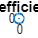


% Define n values for plotting
nVals = -25:25;

% Calculate xtilde(n)
xtilde_1 = zeros(1, length(nVals));
for idx = 1:length(nVals)
    n = nVals(idx);
    x_tilde_1(idx) = (1 / sqrt(2 * N_1 + 1)) * sum(FsCoeffs_1 .* exp(1i * (-N_1:N_1) * (2 * pi / (2 * N_1 + 1)) * n));
end
xtilde_2 = zeros(1, length(nVals));
for idx = 1:length(nVals)
    n = nVals(idx);
    x_tilde_2(idx) = (1 / sqrt(2 * N_2 + 1)) * sum(FsCoeffs_2 .* exp(1i * (-N_2:N_2) * (2 * pi/(2 * N_2 + 1)) * n));
end
xtilde_3 = zeros(1, length(nVals));
for idx = 1:length(nVals)
    n = nVals(idx);
    x_tilde_3(idx) = (1 / sqrt(2 * N_3 + 1)) * sum(FsCoeffs_3 .* exp(1i * (-N_3:N_3) * (2 * pi / (2 * N_3 + 1)) * n));
end
xtilde_4 = zeros(1, length(nVals));
for idx = 1:length(nVals)
    n = nVals(idx);
    x_tilde_4(idx) = (1 / sqrt(2 * N_4 + 1)) * sum(FsCoeffs_4 .* exp(1i * (-N_4:N_4) * (2 * pi / (2 * N_4 + 1)) * n));
end

% Plot the Fourier series coefficients, xtilde, and x
figure;
stem(-N_1:N_1, abs(FsCoeffs_1));
xlabel('k');
ylabel('|a_k|');
title(['Fourier Series Coefficients (N = ', num2str(N_1), ', N1 = ', num2str(N1_1), ')']);

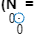

figure;
stem(nVals, xtilde_1);
xlabel('n');
ylabel('x\_tilde_1(n)');
title(['x\_tilde_1(n) (N = ', num2str(N_1), ', N1 = ', num2str(N1_1), ')']);

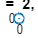

figure;
stem(-N_1:N_1, x_1);
xlabel('n');
ylabel('x_1(n)');
title(['x_1(n) (N = ', num2str(N_1), ', N1 = ', num2str(N1_1), ')']);

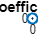


figure;
stem(-N_2:N_2, abs(FsCoeffs_2));
xlabel('k');
ylabel('|a_k|');
title(['Fourier Series Coefficients (N = ', num2str(N_2), ', N1 = ', num2str(N1_2), ')']);

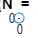

figure;
stem(nVals, xtilde_2);
xlabel('n');
ylabel('x\_tilde_2(n)');
title(['x\_tilde_2(n) (N = ', num2str(N_2), ', N1 = ', num2str(N1_2), ')']);

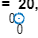

figure;
stem(-N_2:N_2, x_2);
xlabel('n');
ylabel('x_2(n)');
title(['x_2(n) (N = ', num2str(N_2), ', N1 = ', num2str(N1_2), ')']);

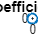


figure;
stem(-N_3:N_3, abs(FsCoeffs_3));
xlabel('k');
ylabel('|a_k|');
title(['Fourier Series Coefficients (N = ', num2str(N_3), ', N1 = ', num2str(N1_3), ')']);

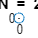

figure;
stem(nVals, xtilde_3);
xlabel('n');
ylabel('x\_tilde_3(n)');
title(['x\_tilde_3(n) (N = ', num2str(N_3), ', N1 = ', num2str(N1_3), ')']);

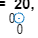

figure;
stem(-N_3:N_3, x_3);
xlabel('n');
ylabel('x_3(n)');
title(['x_3(n) (N = ', num2str(N_3), ', N1 = ', num2str(N1_3), ')']);

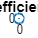


figure;
stem(-N_4:N_4, abs(FsCoeffs_4));
xlabel('k');
ylabel('|a_k|');
title(['Fourier Series Coefficients (N = ', num2str(N_4), ', N1 = ', num2str(N1_4), ')']);

figure;
stem(nVals, xtilde_4);
xlabel('n');
ylabel('x\_tilde_4(n)');
title(['x\_tilde_4(n) (N = ', num2str(N_4), ', N1 = ', num2str(N1_4), ')']);

figure;
stem(-N_4:N_4, x_4);
xlabel('n');
ylabel('x_4(n)');
title(['x_4(n) (N = ', num2str(N_4), ', N1 = ', num2str(N1_4), ')']);


% x_tilde(n) is the Fourier series approximation of the input signal x(n). The Fourier series
% coefficients represent the frequency component, and using the Fourier series expansion, the 
% input signal x, can be approximated by a signal x_tilde(n). x_tilde(n) can be reconstructed 
% using these coefficients. The approximation tends to be more accurate when the number of 
% coefficients is larger, as it can represent more complex frequency content in the signal.

# Q3 Fourier Transform

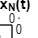

t = linspace(0,2,1000); 

P = 2; 

N_1 = 5;
N_2 = 10;
N_3 = 15;

%plot
figure; 
hold on; 
xN_1 = Q3FourierTransform(t, N_1, P);
plot(t, real(xN_1), 'DisplayName', sprintf('N = %d', N_1));
xN_2 = Q3FourierTransform(t, N_2, P);
plot(t, real(xN_2), 'DisplayName', sprintf('N = %d', N_2));
xN_3 = Q3FourierTransform(t, N_3, P);
plot(t, real(xN_3), 'DisplayName', sprintf('N = %d', N_3));

xlabel('t');
ylabel('x_N');
title('Plot of Signal x_{N}(t) for N = 5,10,15');
legend('show'); 


% Define signal x 
x = @(t) (t <= 1) .* (t) + ((t >= 1) & (t <= 2)) .* (1 - t);
xVals = x(t);

% Define signal xN
coeffs_1 = 0;
coeffsSum_1 = 0;
for k = -N_1:N_1
    coeffs_1 = Q3FourierSeriesCoeffs(k, P) * 1 / sqrt(2) * exp(1i * 2 * pi * k / 2);
    coeffsSum_1 = coeffsSum_1 + coeffs_1;
end
xN_1 = @(t) coeffsSum_1 * exp(t);

coeffs_2 = 0;
coeffsSum_2 = 0;
for k = -N_2:N_2
    coeffs_2 = Q3FourierSeriesCoeffs(k, P) * 1 / sqrt(2) * exp(1i * 2 * pi * k / 2);
    coeffsSum_2 = coeffsSum_2 + coeffs_2;
end
xN_2 = @(t) coeffsSum_2 * exp(t);

coeffs_3 = 0;
coeffsSum_3 = 0;
for k = -N_3:N_3
    coeffs_3 = Q3FourierSeriesCoeffs(k, P) * 1 / sqrt(2) * exp(1i * 2 * pi * k / 2);
    coeffsSum_3 = coeffsSum_3 + coeffs_3;
end
xN_3 = @(t) coeffsSum_3 * exp(t);

% Caluclate the integral of the squared error between x and xN
limNtoInfin_1 = integral(@(t) ((x(t) - xN_1(t)).^2), 0, 2);
limNtoInfin_2 = integral(@(t) ((x(t) - xN_2(t)).^2), 0, 2);
limNtoInfin_3 = integral(@(t) ((x(t) - xN_3(t)).^2), 0, 2);

% Display the integral of the squared error between x and xN
fprintf('The integral of the squared error between x and xN_1 is: %d', limNtoInfin_1);

The integral of the squared error between x and xN_1 is: 8.102688e+00

fprintf('The integral of the squared error between x and xN_2 is: %d', limNtoInfin_2);

The integral of the squared error between x and xN_2 is: 8.484962e+00

fprintf('The integral of the squared error between x and xN_3 is: %d', limNtoInfin_3);

The integral of the squared error between x and xN_3 is: 8.706562e+00


% By the properties of Hilbert spaces along with the implications that  the set of functions 
% {sqrt(1/P)e^(i2πk/P*t)} forms a complete orthonormal sequence, we can represent any x(t) in 
% L2([0, 2]; C) as a sum of the basis functions spanning this space. As N increases to infinity,  
% the error R((x(t) - xN(t))^2 dt) will decrease to 0, implying xN(t) converges to x(t) in the 
% L2([0, 2]; C) space. This a property of the Fourier series representation in a Hilbert space.

% As can be seen by the results of taking the integral of the squared error between x and xN, 
% for increasing values of N, (5, 10, 15), the integral of the squared difference does not
% corroborate the properties of Hilbert spaces, suggesting an error in the method of calcultation, 
% or perhaps the increases in N were not sufficient to show that the reconstruction error does 
% indeed approach zero as N approaches infinity. However, I will include my attempt.

% Caluclate the maximum absolute error between x and xN
LimSupNtoInfin_1 = norm(x(t) - xN_1(t), "inf");
LimSupNtoInfin_2 = norm(x(t) - xN_2(t), "inf");
LimSupNtoInfin_3 = norm(x(t) - xN_3(t), "inf");

% Display the maximum absolute error between x and xN
fprintf('The maximum absolute error between x and xN_1 is: %d', LimSupNtoInfin_1);

The maximum absolute error between x and xN_1 is: 4.447200e+00

fprintf('The maximum absolute error between x and xN_2 is: %d', LimSupNtoInfin_2);

The maximum absolute error between x and xN_2 is: 4.545287e+00

fprintf('The maximum absolute error between x and xN_3 is: %d', LimSupNtoInfin_3);

The maximum absolute error between x and xN_3 is: 4.601066e+00


% With respect to the signal x used in this question, as can be seen by the above results; the 
% maximum absolute error between x and xN over the interval of t is in [0, 2], increases for larger 
% values of N. Extrapolating this finding would suggest that for a genereal signal in L2([0, 2];C), 
% the convergence of xN(t) to x(t) as N approaches infinity, would also not hold.

% Additionally, for a general x(t) is in L2([0, 2]; C), the convergence of xN(t) to x(t) in the L2 sense 
% does not guarantee pointwise convergence. Convergence in L2 is a sort of global convergence in the sense 
% that overall, the error between the input signal and its approximation may be small when integrated 
% over the entire interval, however, at particular points within the interval it can be relatively large. 

% Response is further ellaborated on in the Microsoft Word submission file


# Q4 Low-Pass Filters and Noise Removal

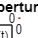

% Plot input signal x and ouptut signal y
figure
xt = @(t) 10 * exp(-t.^2 / 2); 
yt = @(t) 20 * cos(pi * 8 * t) + 2 * sin(pi * 8 * t) + 10 * exp(-t.^2 / 2);
fplot(xt, [0, 10]); 
hold on;
fplot(yt, [0, 10]);

% Format plot
xlabel('time, t');
ylabel('frequency, f');
title('Input signal and perturbed output signal');
legend('x(t)', 'y(t)');

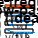


% Ideal low-pass filter design
fc = 8; 
fs = 16; 

% Define time vector beginning at 0, increasing in increments of (1/fs),
% until a final values of (8-1/fs)
t = 0:(1 / fs):(8 - 1 / fs); 
x =  10 * exp(-t.^2 / 2); 
y = 10 * exp(-t.^2 / 2) + 20 * cos(pi * fc * t) + 2 * sin(pi * fc * t); 

% Input FFT size
N = 128; 
X = fftshift(fft(x,N)); 
df = fs/N; 
sampleIndex = -N/2:N/2-1; 
f = sampleIndex * df; 

% Frequency domain representation of ideal low-pass filter 
fc1 = 5;
H_f = zeros(size(f)); 
H_f(abs(f) <= fc1) = 1; 

% Apply filter to signal in frequency domain
y_filt_f = ifftshift(fft(x)).*(H_f);    
% Apply inverse fourier transform
y_filt_n = real(ifft(ifftshift(y_filt_f))); 

% Plot original x signal
subplot (411); 
plot (t, x); 
hold on;
plot(t, y);
xlabel('Time, t'); 
ylabel('Amplitude'); 
title ('Original x signal and y signal'); 
legend('x(t)', 'y(t)');
% Plot signal filtered in the frequency domain
subplot(412); 
plot(f, real(y_filt_f)); 
xlabel('Time, t'); 
ylabel('Frequency, f'); 
title('y Signal in the frequency domain'); 
% Plot ideal low-pass filter
subplot(413); 
plot(f, H_f); 
xlabel('Time, t'); 
ylabel('Frequency, f'); 
title('Ideal low-pass filter'); 
% Plot filtered continuous time signal
subplot(414); 
plot(t, y_filt_n); 
xlabel('Time, t'); 
ylabel('Amplitude'); 
title('Filtered y signal (ideal low-pass filter)'); 

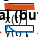


% Define filter order and cuttoff frequency
order = 5; 
fcutoff = 1; 

% Define sampling frequency and normalized cutoff frequency
fs = 1/ (t(2)-t(1));
fcutoffNorm = fcutoff / (fs/2); 

% Generate butterworth filter inputs 
[b,a] = butter(order, fcutoffNorm, 'low'); 

% Apply filter to signal y
y_filtered = filter(b, a, y); 

% Plot original x signal
figure; 
subplot(3, 1, 1); 
plot(t, x, 'linewidth', 1); 
hold on;
plot(t, y, 'linewidth', 1); 
xlabel('Time, t'); 
ylabel('Amplitude'); 
title('Original x signal and y signal'); 
xlim([0 max(t)]); 
legend('x(t)', 'y(t)');
% Plot filtered ouput
subplot(3, 1, 3); 
plot(t, y_filtered, 'linewidth', 1); 
xlabel('Time, t'); 
ylabel('Amplitude'); 
title('Filtered y signal (butterworth filter)'); 
xlim([0 max(t)]); 

# Q5 Sampling

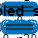

% Decimate x_1 by a factor of 4
n = -100:100;
x_1 = cos(0.16 * pi * n);
M = 4;
y_1 = Q5dnsample(x_1, M);

% Plot input signal x_1
figure;
subplot(2,1,1);
stem(n, x_1);
xlabel('n');
ylabel('x_1(n)');
title('Original signal x_1(n)');
% Plot output signal y_1 (decimated x_1)
subplot(2,1,2);
stem(0:4:length(x1)-1, y1);
xlabel('n');
ylabel('y_1(n)');
title('Downsampled signal y_1(n)');

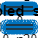


% Decimate x_2 by a factor of 4
x_2 = cos(0.8 * pi * n);
y_2 = Q5dnsample(x2, M);

% Plot input signal x_2
figure;
subplot(2, 1, 1);
stem(n, x_2);
xlabel('n');
ylabel('x_2(n)');
title('Original signal x_2(n)');
% Plot output signal y_2 (decimated x_2)
subplot(2, 1, 2);
stem(0:4:length(x2)-1, y2);
xlabel('n');
ylabel('y_2(n)');
title('Downsampled signal y_2(n)');

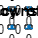


% Generate Fourier transform for signals, x_1, y_1, x_2, y_2
X_1 = fftshift(fft(x_1),length(n));
Y_1 = fftshift(fft(y_1),length(n));
X_2 = fftshift(fft(x_2),length(n));
Y_2 = fftshift(fft(y_2),length(n));
fs = length(n);
frequencies = linspace(-fs/2, fs/2, length(n));

% Plot X_1
figure;
subplot(2, 2, 1);
plot(frequencies, abs(X_1));
xlabel('Frequency (rad/s)');
ylabel('X_1(f)');
title('Frequency of x_1(n)');
% Plot Y_1
fs = length(y_1);
frequencies = linspace(-fs/2, fs/2, length(y1));
subplot(2, 2, 2);
plot(frequencies, abs(Y_1));
xlabel('Frequency (rad/s)');
ylabel('Y_1(f)');
title('Frequency of Downsampled x_1(n) = y1(n)');
% Plot X_2
fs = length(n);
frequencies = linspace(-fs/2, fs/2, length(n));
subplot(2, 2, 3);
plot(frequencies, abs(X_2));
xlabel('Frequency (rad/s)');
ylabel('|X_2(f)|');
title('Frequency of x_2(n)');
% Plot Y_2
fs = length(y_2);
frequencies = linspace(-fs/2, fs/2, length(y2));
subplot(2, 2, 4);
plot(frequencies, abs(Y_2));
xlabel('Frequency (rad/s)');
ylabel('|Y_2(f)|');
title('Frequency of Downsampled x_2(n) y2(n)');


% The downsampled signal, y_1(n), can be used to recover the input signal as the highest frequency 
% of the signal is much less than the Nyquist frequency. The downsampled signal, y_1(n), can also 
% be used to recover the input signal, however the highest frequency of the signal is very close to 
% the Nyquist frequency, where downsampling causes aliasing. 

% The maximum frequency that can be recovered from a down-sampled signal is half the original sampling 
% frequency. In this case, the original sampling frequency is 1 sample per unit of time (since n represents 
% time), so the Nyquist frequency is 0.5 cycles per unit of time (i.e., the maximum frequency that can be 
% represented without aliasing is 0.5 cycles per unit of time). When the signal is down-sampled by a factor 
% of 4, the new sampling frequency becomes 0.25 cycles per unit of time (i.e., the new sampling period is 4 
% times longer), so the maximum frequency that can be recovered from the down-sampled signal is 0.125 
% cycles per unit of time. By examining the frequency plots of the down-sampled signals (Y_1 and Y_2), 
% we can see that their highest frequency components are below 0.125 cycles per unit of time, which means 
% that the signals can be reconstructed from the down-sampled versions without aliasing. Therefore, in this 
% case, the maximum frequency that can be recovered from the down-sampled signal is 0.125 cycles per unit of time